syms p1x p2x r a B t
% a = c/2
p1y = tan(B) * p1x

$$p1y = \mathrm{p1x}\,\tan\left(B\right)$$

p2y = sqrt(r^2 - (p2x - a)^2)

$$p2y = \sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}}$$


P1 = [p1x; p1y]

$$P1 = \left(\begin{array}{c} \mathrm{p1x}\\ \mathrm{p1x}\,\tan\left(B\right) \end{array}\right)$$

P2 = [p2x; p2y]

$$P2 = \left(\begin{array}{c} \mathrm{p2x}\\ \sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}} \end{array}\right)$$


L_dot = tan(B)

$$L\_dot = \tan\left(B\right)$$

C_dot = (r^2 - (p2x - a)^2)^(-3/2) * (p2x - a)

$$C\_dot = -\frac{a-\mathrm{p2x}}{{\left(r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}\right)}^{3/2}}$$


P_m = P1 + [1; L_dot] * [1 0] * [1, 1; L_dot, C_dot] * (P2 - P1)

$$P\_m = \left(\begin{array}{c} \mathrm{p2x}-\mathrm{p1x}\,\tan\left(B\right)+\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}}\\ \mathrm{p1x}\,\tan\left(B\right)-\tan\left(B\right)\,\left(\mathrm{p1x}\,\tan\left(B\right)-\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}}\right)-\tan\left(B\right)\,\left(\mathrm{p1x}-\mathrm{p2x}\right) \end{array}\right)$$


B_dot = -2 * (1 - t) * P1 - 2 * t * P_m + 2 * (1 - t) * P_m + 2 * t * P2

$$B\_dot = \begin{array}{l} \left(\begin{array}{c} \mathrm{p1x}\,\left(2\,t-2\right)-2\,t\,\left(\mathrm{p2x}-\mathrm{p1x}\,\tan\left(B\right)+\sigma_{2}\right)+2\,\mathrm{p2x}\,t-\left(2\,t-2\right)\,\left(\mathrm{p2x}-\mathrm{p1x}\,\tan\left(B\right)+\sigma_{2}\right)\\ \left(2\,t-2\right)\,\sigma_{1}+2\,t\,\sigma_{1}+2\,t\,\sigma_{2}+\mathrm{p1x}\,\tan\left(B\right)\,\left(2\,t-2\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\tan\left(B\right)\,\left(\mathrm{p1x}\,\tan\left(B\right)-\sigma_{2}\right)-\mathrm{p1x}\,\tan\left(B\right)+\tan\left(B\right)\,\left(\mathrm{p1x}-\mathrm{p2x}\right)\\ \sigma_{2}=\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}} \end{array}$$

B_dot0 = subs(B_dot, t, 0)

$$B\_dot0 = \left(\begin{array}{c} 2\,\mathrm{p2x}-2\,\mathrm{p1x}-2\,\mathrm{p1x}\,\tan\left(B\right)+2\,\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}}\\ -2\,\tan\left(B\right)\,\left(\mathrm{p1x}\,\tan\left(B\right)-\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}}\right)-2\,\tan\left(B\right)\,\left(\mathrm{p1x}-\mathrm{p2x}\right) \end{array}\right)$$

B_dot1 = subs(B_dot, t, 1)

$$B\_dot1 = \left(\begin{array}{c} 2\,\mathrm{p1x}\,\tan\left(B\right)-2\,\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}}\\ 2\,\tan\left(B\right)\,\left(\mathrm{p1x}\,\tan\left(B\right)-\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}}\right)-2\,\mathrm{p1x}\,\tan\left(B\right)+2\,\tan\left(B\right)\,\left(\mathrm{p1x}-\mathrm{p2x}\right)+2\,\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}} \end{array}\right)$$


s1 = B_dot0(2) / B_dot0(1)

$$s1 = \frac{2\,\tan\left(B\right)\,\left(\mathrm{p1x}\,\tan\left(B\right)-\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}}\right)+2\,\tan\left(B\right)\,\left(\mathrm{p1x}-\mathrm{p2x}\right)}{2\,\mathrm{p1x}-2\,\mathrm{p2x}+2\,\mathrm{p1x}\,\tan\left(B\right)-2\,\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}}}$$

s2 = B_dot1(2) / B_dot0(1)

$$s2 = \begin{array}{l} -\frac{2\,\tan\left(B\right)\,\left(\mathrm{p1x}\,\tan\left(B\right)-\sigma_{1}\right)-2\,\mathrm{p1x}\,\tan\left(B\right)+2\,\tan\left(B\right)\,\left(\mathrm{p1x}-\mathrm{p2x}\right)+2\,\sigma_{1}}{2\,\mathrm{p1x}-2\,\mathrm{p2x}+2\,\mathrm{p1x}\,\tan\left(B\right)-2\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}} \end{array}$$


eq1 = L_dot == s1

$$eq1 = \tan\left(B\right)=\frac{2\,\tan\left(B\right)\,\left(\mathrm{p1x}\,\tan\left(B\right)-\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}}\right)+2\,\tan\left(B\right)\,\left(\mathrm{p1x}-\mathrm{p2x}\right)}{2\,\mathrm{p1x}-2\,\mathrm{p2x}+2\,\mathrm{p1x}\,\tan\left(B\right)-2\,\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}}}$$

eq2 = C_dot == s2

$$eq2 = \begin{array}{l} -\frac{a-\mathrm{p2x}}{{\left(r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}\right)}^{3/2}}=-\frac{2\,\tan\left(B\right)\,\left(\mathrm{p1x}\,\tan\left(B\right)-\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}}\right)-2\,\mathrm{p1x}\,\tan\left(B\right)+2\,\tan\left(B\right)\,\left(\mathrm{p1x}-\mathrm{p2x}\right)+\sigma_{1}}{2\,\mathrm{p1x}-2\,\mathrm{p2x}+2\,\mathrm{p1x}\,\tan\left(B\right)-\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=2\,\sqrt{r^{2}-{\left(a-\mathrm{p2x}\right)}^{2}} \end{array}$$


[px1, px2] = solve([eq1, eq2], [p1x, p2x])

 
px1 =
 
Empty sym: 0-by-1
 
 
px2 =
 
Empty sym: 0-by-1
 


syms t x1 x2 y1 y2 m
x_m = (y2 - y1) / m + x1;
B1 = (1 - t)^2 * x1 + 2 * (1 - t) * t * xm + t^2 * x2;
B2 = (1 - t)^2 * y1 + 2 * (1 - t) * t * y2 + t^2 * y2;

B1_dot = diff(B1, t, 1)

$$B1\_dot = x_{1}\,\left(2\,t-2\right)-\mathrm{xm}\,\left(2\,t-2\right)+2\,t\,x_{2}-2\,t\,\mathrm{xm}$$

B2_dot = diff(B2, t, 1)

$$B2\_dot = y_{1}\,\left(2\,t-2\right)-y_{2}\,\left(2\,t-2\right)$$

B1_ddot = diff(B1, t, 2)

$$B1\_ddot = 2\,x_{1}+2\,x_{2}-4\,\mathrm{xm}$$

B2_ddot = diff(B2, t, 2)

$$B2\_ddot = 2\,y_{1}-2\,y_{2}$$


k = abs(B1_dot * B2_ddot - B2_dot * B1_ddot) / ((B1_dot ^ 2 + B2_dot ^ 2) ^ (3/2))

$$k = \begin{array}{l} \frac{\left|\left(2\,y_{1}-2\,y_{2}\right)\,\sigma_{1}-\left(y_{1}\,\left(2\,t-2\right)-y_{2}\,\left(2\,t-2\right)\right)\,\left(2\,x_{1}+2\,x_{2}-4\,\mathrm{xm}\right)\right|}{{\left({\sigma_{1}}^{2}+{\left(y_{1}\,\left(2\,t-2\right)-y_{2}\,\left(2\,t-2\right)\right)}^{2}\right)}^{3/2}}\\ \mathrm{where}\\ \sigma_{1}=x_{1}\,\left(2\,t-2\right)-\mathrm{xm}\,\left(2\,t-2\right)+2\,t\,x_{2}-2\,t\,\mathrm{xm} \end{array}$$


k = simplify(subs(k, t, 1))

$$k = \frac{\left|\left(2\,x_{2}-2\,\mathrm{xm}\right)\,\left(2\,y_{1}-2\,y_{2}\right)\right|}{8\,{\left({\left(x_{2}-\mathrm{xm}\right)}^{2}\right)}^{3/2}}$$

 
ans =
 
Empty sym: 0-by-1
 


$$xm = x_{1}-\frac{y_{1}-y_{2}}{m}$$

$$dx\_dt = x_{1}\,\left(2\,t-2\right)-\left(2\,t-2\right)\,\left(x_{1}-\frac{y_{1}-y_{2}}{m}\right)+2\,t\,x_{2}-2\,t\,\left(x_{1}-\frac{y_{1}-y_{2}}{m}\right)$$

$$dy\_dt = y_{1}\,\left(2\,t-2\right)-y_{2}\,\left(2\,t-2\right)$$

$$d2x\_dt2 = 2\,x_{2}-2\,x_{1}+\frac{4\,\left(y_{1}-y_{2}\right)}{m}$$

$$d2y\_dt2 = 2\,y_{1}-2\,y_{2}$$

$$curvature = \begin{array}{l} \frac{\left|\left(y_{1}\,\left(2\,t-2\right)-y_{2}\,\left(2\,t-2\right)\right)\,\left(2\,x_{2}-2\,x_{1}+\frac{4\,\left(y_{1}-y_{2}\right)}{m}\right)-\left(2\,y_{1}-2\,y_{2}\right)\,\sigma_{1}\right|}{{\left({\left(y_{1}\,\left(2\,t-2\right)-y_{2}\,\left(2\,t-2\right)\right)}^{2}+{\sigma_{1}}^{2}\right)}^{3/2}}\\ \mathrm{where}\\ \sigma_{1}=x_{1}\,\left(2\,t-2\right)-\left(2\,t-2\right)\,\left(x_{1}-\frac{y_{1}-y_{2}}{m}\right)+2\,t\,x_{2}-2\,t\,\left(x_{1}-\frac{y_{1}-y_{2}}{m}\right) \end{array}$$

$$curvature\_at\_1 = \frac{\left|\left(2\,y_{1}-2\,y_{2}\right)\,\left(2\,x_{2}-2\,x_{1}+\frac{2\,\left(y_{1}-y_{2}\right)}{m}\right)\right|}{{\left({\left(2\,x_{2}-2\,x_{1}+\frac{2\,\left(y_{1}-y_{2}\right)}{m}\right)}^{2}\right)}^{3/2}}$$

 
y2_eq =
 
Empty sym: 0-by-1
 


 
y2_eq =
 
Empty sym: 0-by-1
 


x0 = 0

y0 = 0

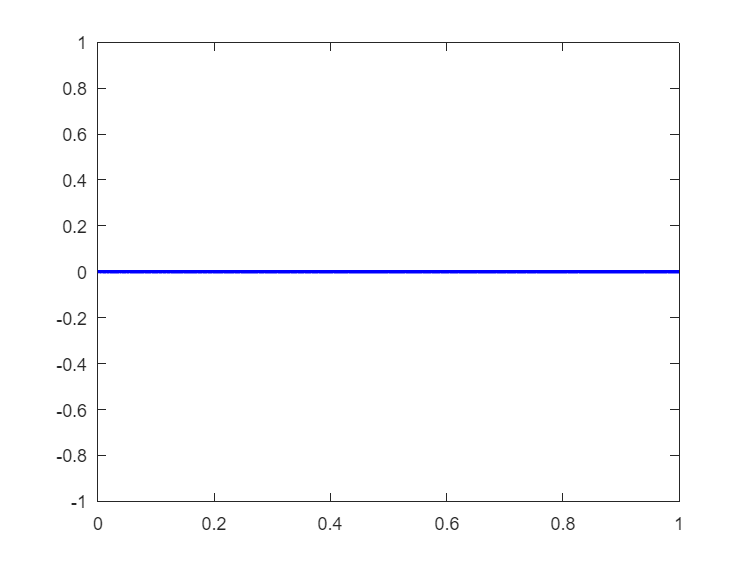

Error using plot
Vectors must be the same length.


p1_sol =

  0×1 empty double column vector




p2_sol =

  0×1 empty double column vector




P1_y_sol =

  0×1 empty double column vector




% solve(subs(k == 1, xm, x_m), [y2])